# Calibration Step 1: Calibrate geometric parameters, g

This script reads in geometric data (as-designed and as-measured/as-manufactured values), and uses this data to plot the prior and posterior estimates of g. 

Input: Data read-in from datafiles/step1/geometry_data.csv

Output: Recreates output shown in Table 1, columns 1-3 in the paper.

clear all;
addpath('utilityfunctions')

% Read in geometry data:
g_data = readtable('datafiles/step1/geometry_data.csv')

g_data = 3×3 table
      parameter       designed    manufactured
    ______________    ________    ____________

    'length'           1828.8         1828    
    'chord_{root}'     435.61          433    
    'chord_{tip}'      261.11          260    


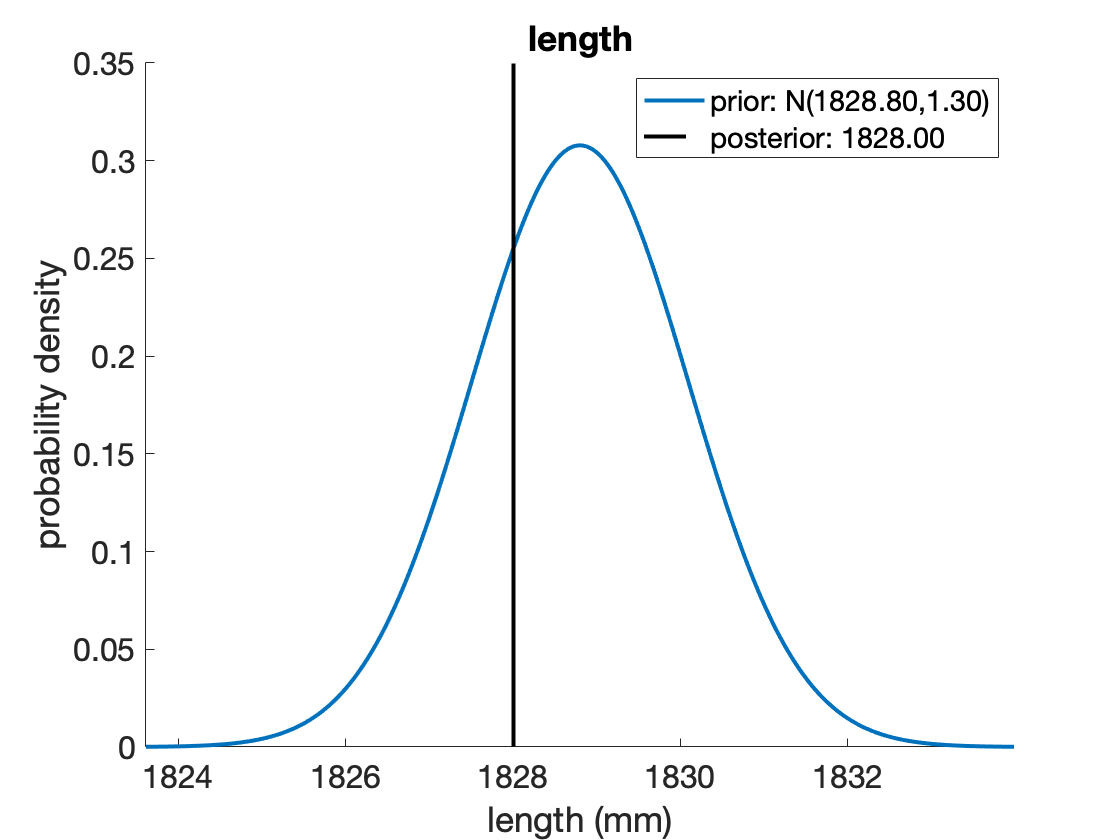

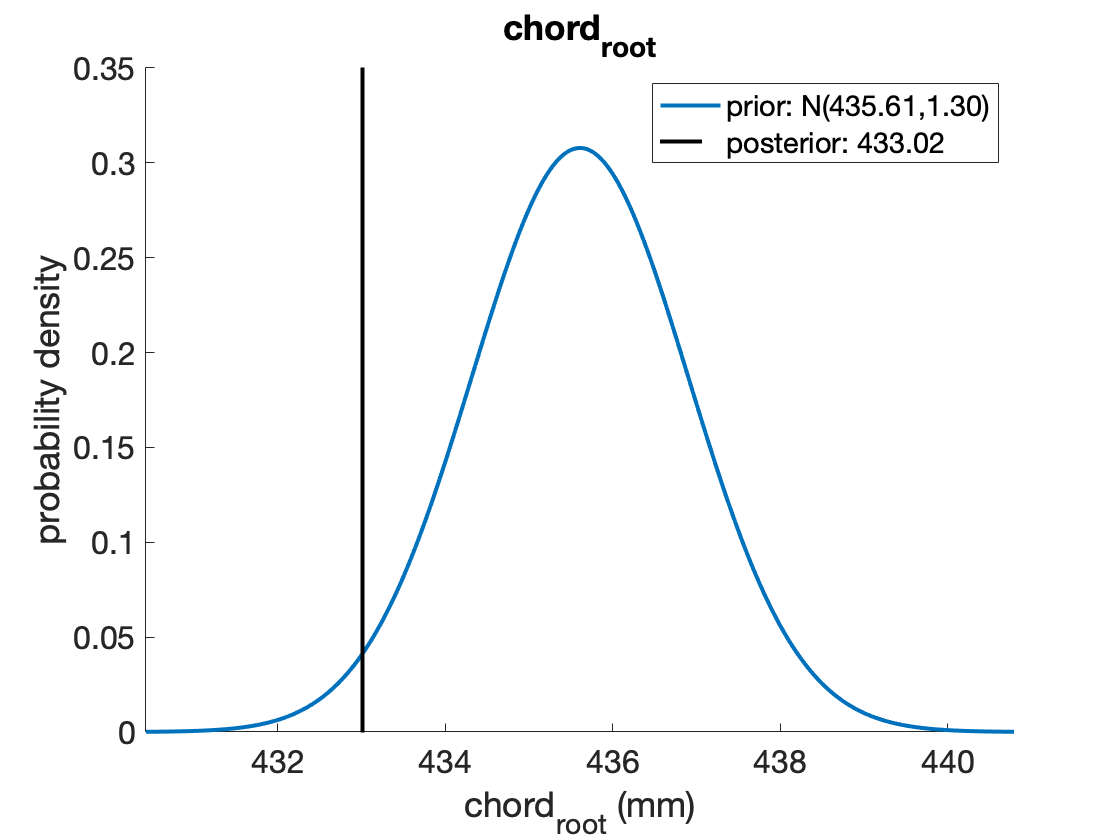

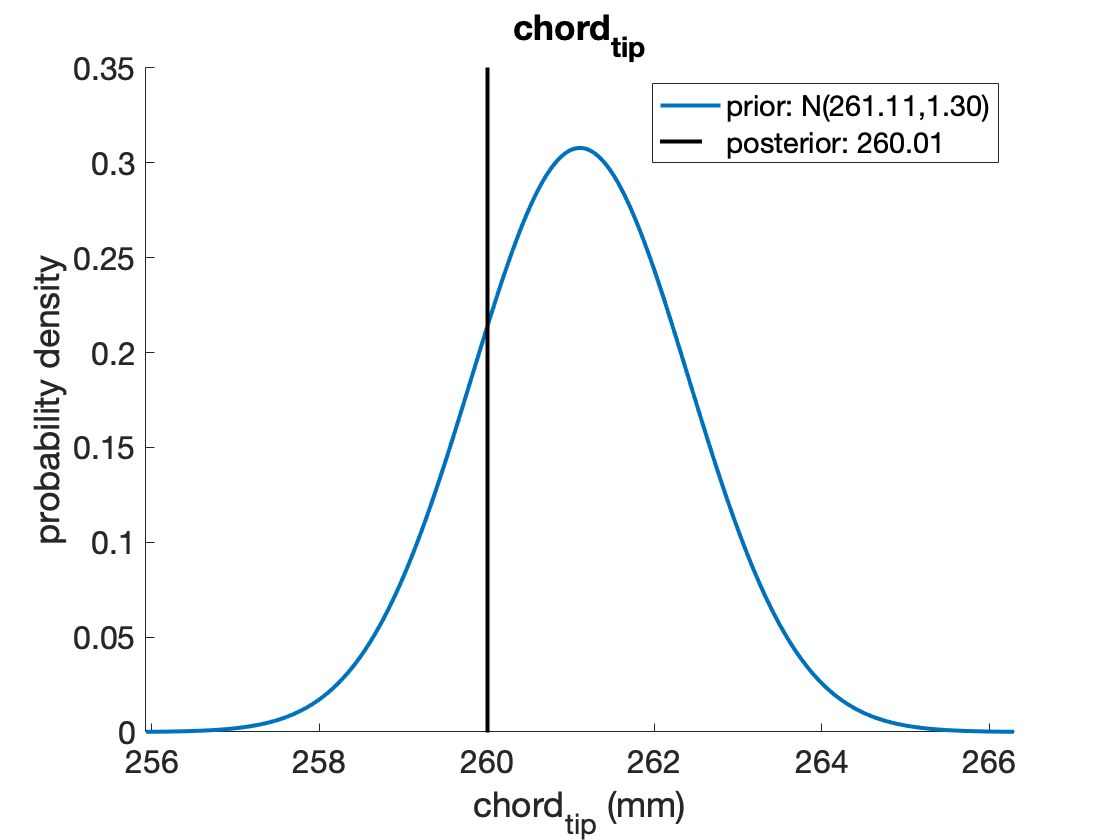


g_0 = g_data.designed; %% prior mean (as-designed) values
deltag_0 = 2.54; %% prior confidence interval half-width

g_hat = g_data.manufactured; %% as-measured/as-manufactured values
deltag_hat = 0.2; %% Measurement uncertainty confidence interval half-width

% loop over each geometric parameter
for i = 1:length(g_0)
    
    % Plot the prior density
    mu_prior = g_0(i);
    sigma_prior = deltag_0/1.96;
    
    figure;
    hold on;
    x_prior = linspace(mu_prior-4*sigma_prior,mu_prior+4*sigma_prior,1000); 
    plot(x_prior, normpdf(x_prior,mu_prior,sigma_prior),'LineWidth',2)
    
    
   % Compute and plot posterior density
    mu_likelihood = g_hat(i);
    sigma_likelihood = deltag_hat/1.96;
    
    %% Compute Gaussian posterior
    [mu_posterior, sigma_posterior] = propagateNormalStatistics(mu_prior,sigma_prior,mu_likelihood,sigma_likelihood);    
    
    %% Plot full posterior distribution
%     x_posterior = linspace(mu_posterior-4*sigma_posterior,mu_posterior+4*sigma_posterior,1000); 
%     plot(x, normpdf(x_posterior,mu_posterior,stddev_posterior),'LineWidth',2)
    
    %% Plot only posterior mean (note that in the paper we ignore the posterior uncertainty, as it is negligibly small)
    stem(mu_posterior, 0.35, 'k','LineWidth',2,'marker','none')
    
    %% format plot
    title(g_data.parameter{i})
    ax = gca;
    set(ax, 'FontSize', 16);
    legend(sprintf('prior: N(%.2f,%.2f)',mu_prior,sigma_prior),sprintf('posterior: %.2f',mu_posterior))
    xlim([min(x_prior),max(x_prior)])
    xlabel(strcat(g_data.parameter{i},' (mm)'))
    ylabel('probability density')
end